# Model-Based Security Threat and Risk Analysis - Risk Estimation

In this section we prioritize the security risks and decide what to do about them. *Risk* is the potential for loss or damage, typically calculated as:

A higher risk value typically means that the particular risk should be prioritized over lower ones. The factors *Impact* and *Feasibility* can be visualized as a risk matrix. [Click here](matlab:tara.functions.showRiskMatrix) or run the following command, to see the risk matrix:

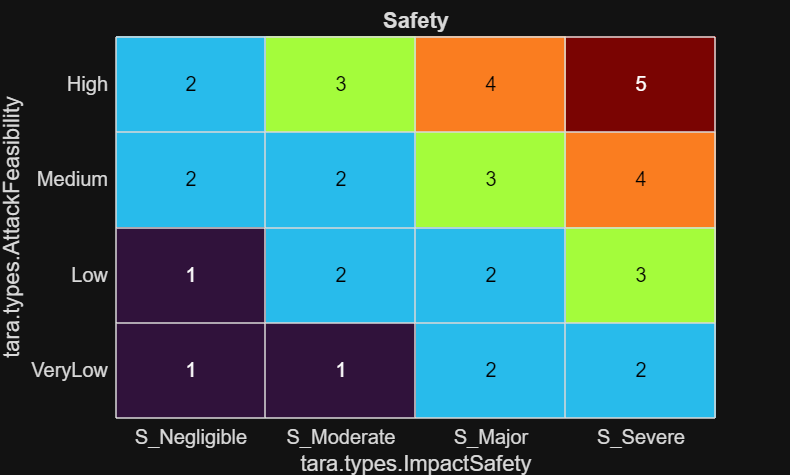

tara.functions.showRiskMatrix

The two axes of the matrix are customizable enumerations - see [Customization](matlab:open('Tutorial_Step11_Customization')) for how to change them. In the following, we show how to use the two factors to automatically calculate the risk, based on the above matrix.

## Preparation

To make sure that everything is set-up correctly please [click here](matlab:openSecurityAnalysis).

Risk calculation and review is done in the threats sheet, based on the defined data types for *Feasibility* and *Impact*. Open the [threats sheet](matlab:open('threats.mldatx')) to start.

## Calculate the Risks

To make sure the risk calculation is up to date, run the *update* function on the [threats sheet](matlab:open('threats.mldatx')):

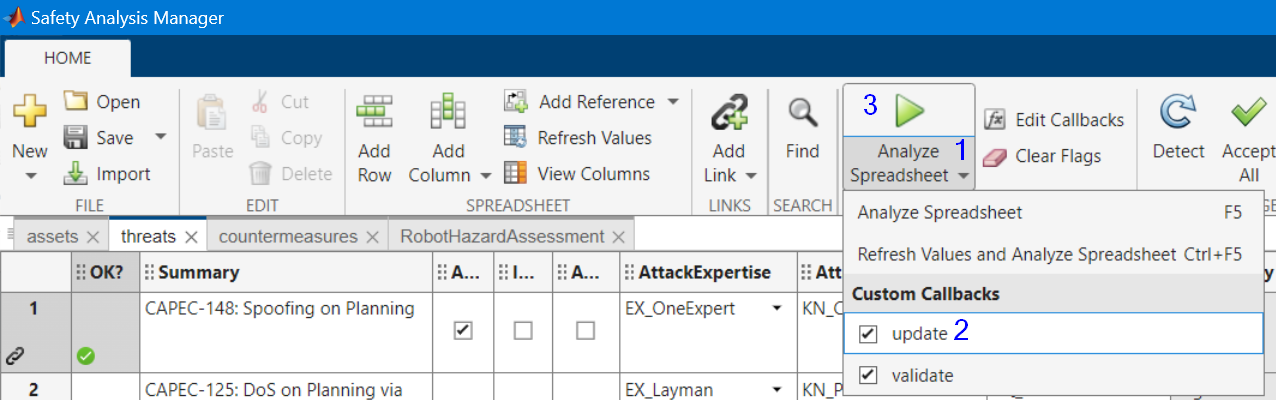

- Open the dropdown menu (1) on the **Analyze Spreadsheet** button,

- then enable the *update* function (2),

- finally click the **Analyze Spreadsheet** button (3).

This collects all data from linked sheets. In particular, it looks into the linked faults column, determines their maximum impact, and writes it back to the derived column **MaxImpact**. This ensures that in the presence of multiple faults, the most severe one is driving the risk value. Finally, the two columns **MaxImpact** and **Feasibility** are used to calculate the derived value **Risk**:

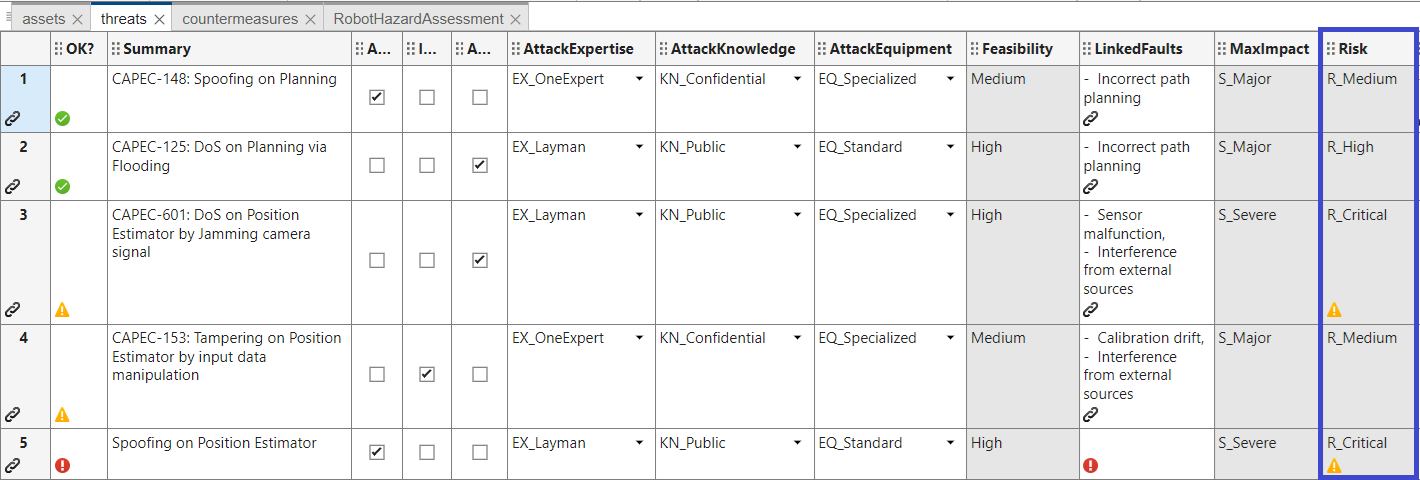

*Note: To inspect or alter the risk calculation logic, right-click on the column header of* ***Risk***, and select ***Edit Formula***. Here, arbitrary MATLAB code can be used. In our case, we use the custom function [`tara.functions.computeRisk`](matlab:open('+tara/+functions/computeRisk.m')) *to evaluate the risk matrix. For more details on that function, see* [*Customization*](matlab:open('Tutorial_Step11_Customization')). *For more help on derived columns and formulas, see* [*documentation*](https://mathworks.com/help/releases/R2024b/fault-analyzer/ref/safetyanalysismanager-app.html#mw_5db05ba9-79e5-41d9-a935-10bee9dc15be)*.*

## Graphical Overview

The risk data and the relation between threats, assets and other elements can be visualized as a graph, which provides insights into their contribution. To show the relationships for a specific sheet entry:

- First select the cell or row in the sheet (e.g., select "CAPEC-601: DoS on Position Estimator" in the threats sheet).

- [Click here](matlab:tara.graph.show) or run the following command to open a graph view:

tara.graph.show

The graph shows the risk relationships for the selected node:

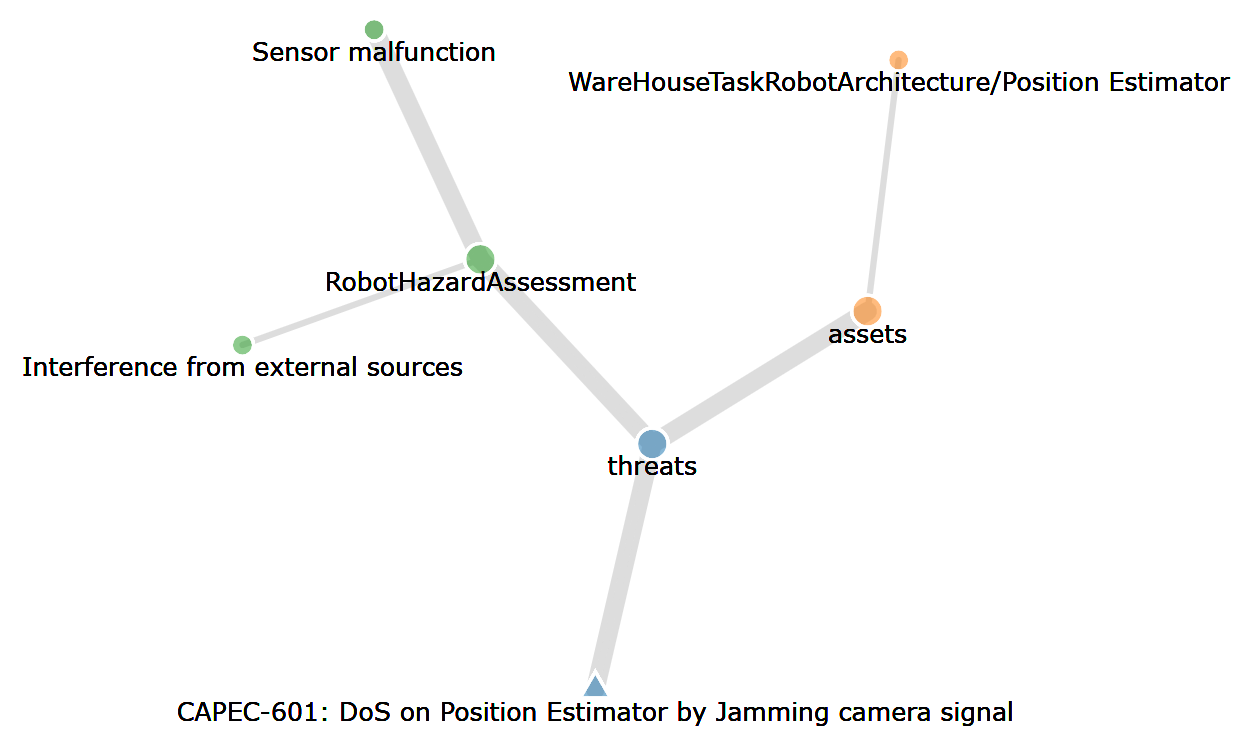

We can see that "CAPEC-601" is a threat, and that it relates to the asset "Position Estimator". Furthermore, we can see that it links to two functional failure from the Hazard Assessment. The graph only shows the directly linked items, not all transitive relations.

To focus on another element, either click on the respective node in the graph, or select another entry in any sheet and click the **Sync** button above the graph. For example, you can show all threats that apply to "Position Estimator" by clicking its row in the [assets sheet](matlab:open('assets.mldatx')), and click the **Sync** button. Alternatively, use **Shift+Left Click** on the graph node "Position Estimator" to directly redraw the graph for it:

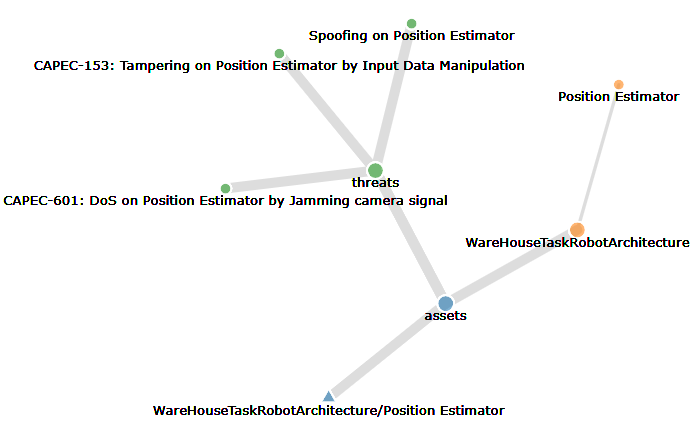

This shows that the asset "Position Estimator" has three threats; it also shows the model links (in orange). You can navigate to each connected items by simply clicking on the node; doing so will navigate to where the item is define (e.g. another analysis table, requirement set, architecture model, etc.).

### Dominance Analysis

The graph can also show information about the importance of each relation, which can be used to prioritize work. 

Towards this:

- Run the *update* function on the [assets sheet](matlab:open('assets.mldatx')), to calculate the dominance information.

- Select the "Position Estimator" by clicking its row in the [assets sheet](matlab:open('assets.mldatx')).

- Click the **Sync** button on the graph.

After that, the graph shows different line widths, e.g., for the threats related to the asset "Position Estimator": 

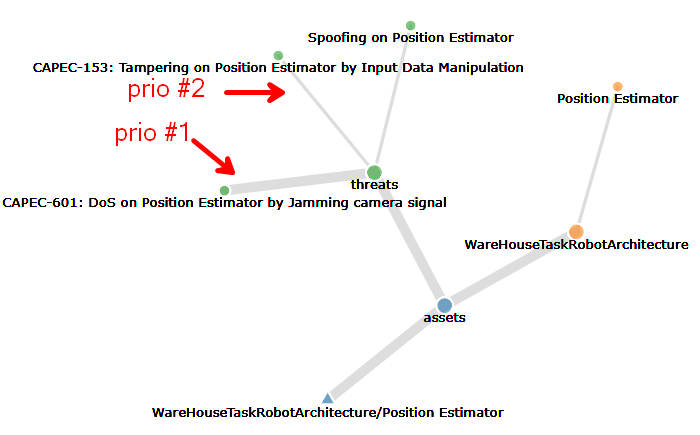

This tells us that "Spoofing" and "DoS" pose a larger threat than "Tampering", and hence should be treated first. This is because they have a higher severity level (S5) than Tampering (S4). 

*Note. A similar analysis could done with attack paths, if our tables would capture capture multiple attacks for each threat (not done in this tutorial).*

## Treatment Decision

For each risk, a treatment decision must be taken. Run the *validate* function on the [threats sheet](matlab:open('threats.mldatx')), to see the warnings about missing decisions. In our sheet, the decision is captured in the column **Status**. By default, its value is set as "Unreviewed", hence all new threats appear with a warning:

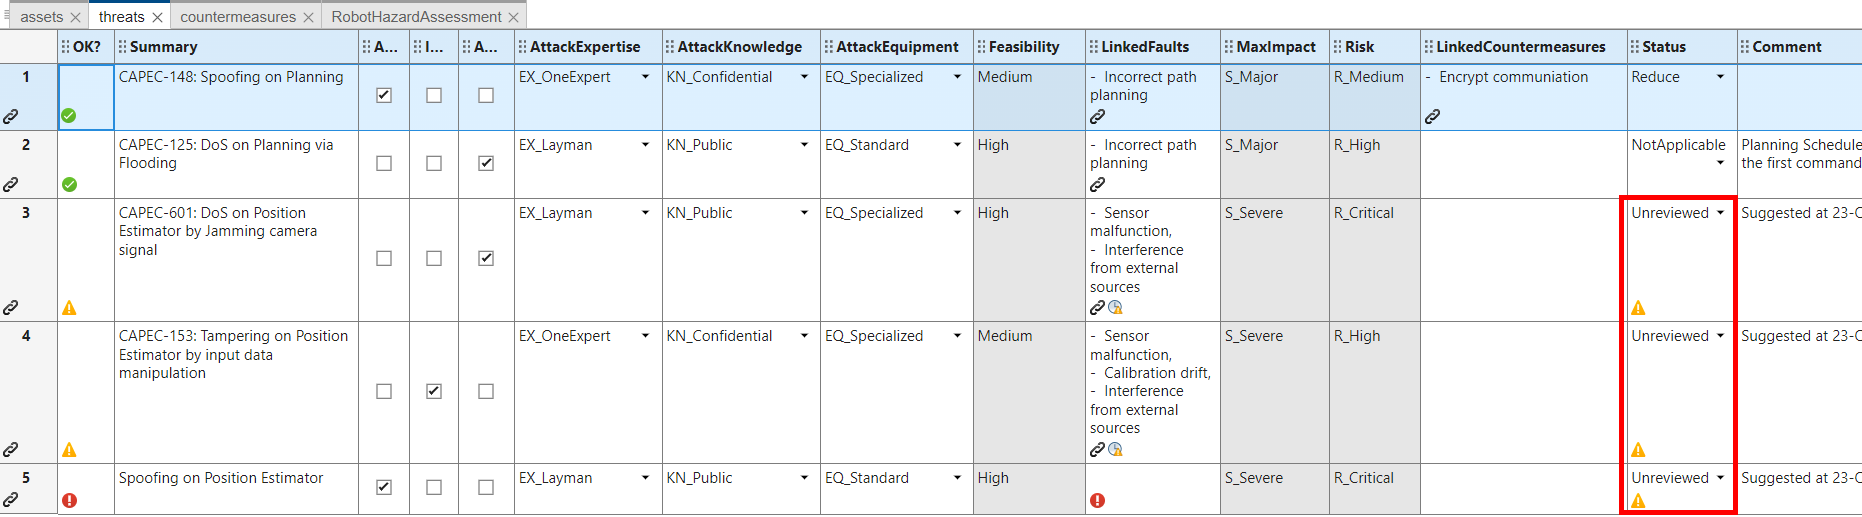

Typically, we have the following decision options:

- Reduce - risk must be lowered by implementing technical countermeasures. This becomes a technical requirement (see [defining security goals and countermeasures](matlab:open('Tutorial_Step05_SecurityGoal'))).

- Avoid - risk must be fully avoided, e.g., by removing a functionality. This becomes a technical requirement, too (see [defining security goals and countermeasures](matlab:open('Tutorial_Step05_SecurityGoal'))).

- Share - risk is transferred to insurance, user, third parties etc.

- Retain - risk is accepted "as is", without any further steps.

- Not Applicable - threat does not exist in this system, so nothing further to do.

For the purpose of this example, we make the following treatment decisions:

### Risk Acceptance Threshold and Correction

Run the *validate* function again, to check if the treatment decisions are suitable. You will get the following result:

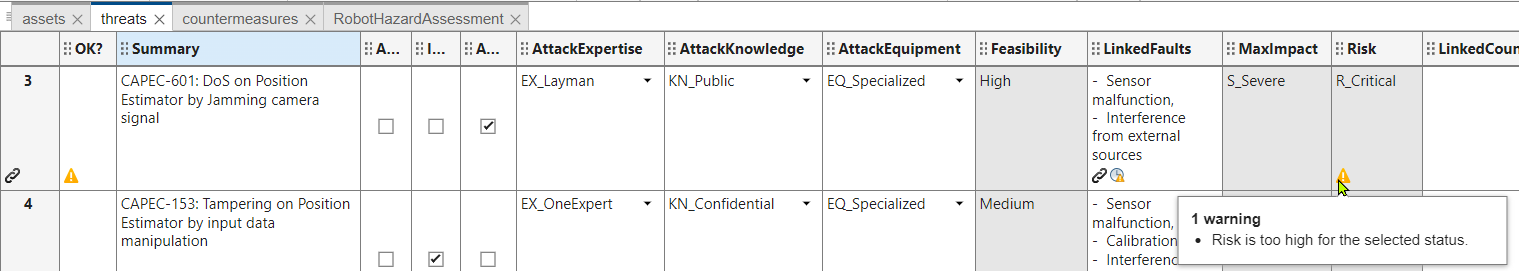

This warning tells us, that we are not allowed to retain the risk of the DoS threat, because it is too high. In our current risk model, the risk acceptance threshold is *medium*, i.e., we cannot pass validation with this decision. Thus, we change the decision **Reduce**, indicating that we intend to build a technical countermeasure for this.

If you want to modify your risk acceptance threshold, see [Customization](matlab:open('Tutorial_Step11_Customization')).

## Final Result and Validation

After risk calculation and treatment decisions, your [threats sheet](matlab:open('threats.mldatx')) should look as follows: 

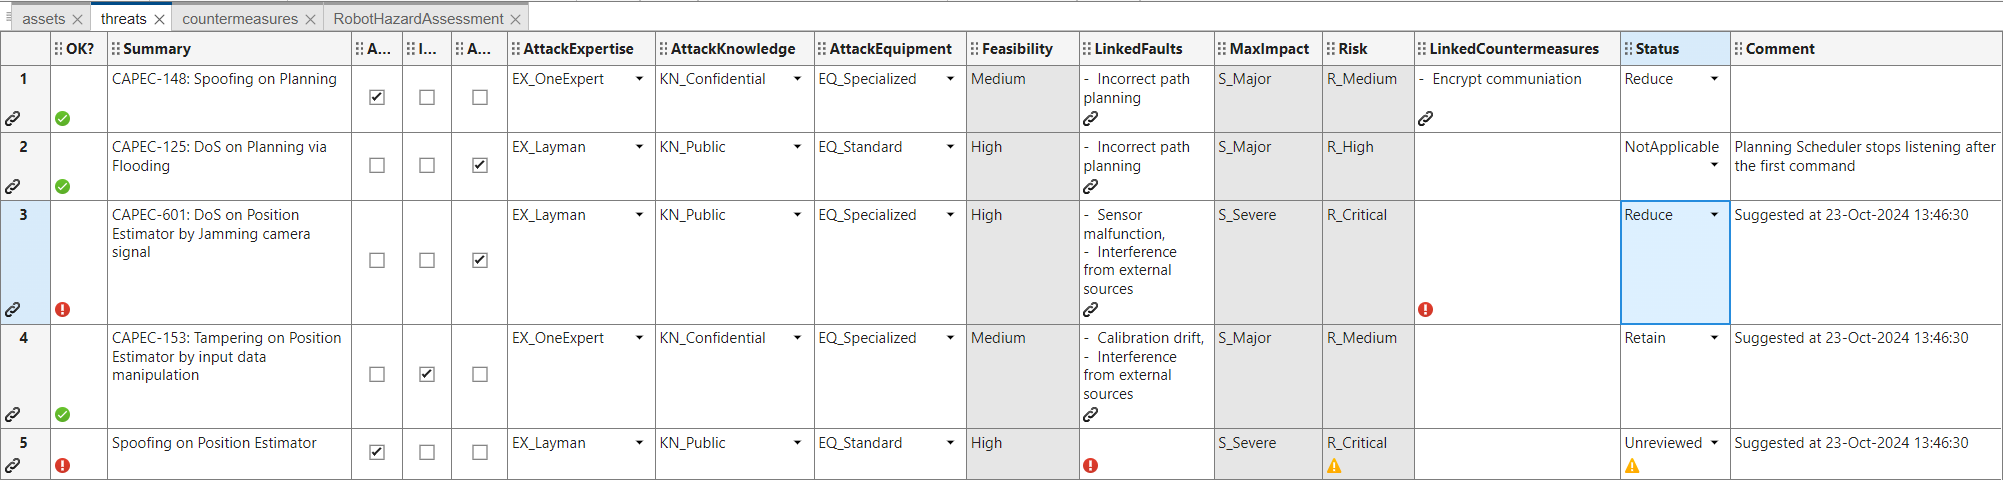

Threats that are set to **Retain** are now shown in green, indicating that no more work is necessary. The threat CAPEC-601 is shown with a red warning, because it was decided to reduce the risk, but a countermeasure is yet missing. The threat "Spoofing on Position Estimator" is left uncompleted.

## What's next?

Before you go to next steps [click here](matlab:saveAll()) to save all artifacts.

We continue with [defining security goals and countermeasures](matlab:open('Tutorial_Step05_SecurityGoal')) or go back to the [overview page](matlab:open('Tutorial')).